# Simulating the BCM Rule

This live script is written for simulating the BCM Rule, in part the experiments performed in Udeigwe *et al. *(2017). Here we differ from that paper because we treat the continuous differential equation of the threshold and weight update rules as discrete time difference updates.

The document below contains code for 4 different tests run on the BCM-trained neuron. 

- The test done in Udeigwe *et al.* using contrived outputs that conform to our stability requirements. This test demonstrates the selectivity this training rule demonstrates between outputs.

- A test similar to the one done for the Simple Hebbian and Oja Rules for differentiation between patterned and random inputs. (95% random and 5% patterned input with identical magnitudes).

- A test done for "recollection" with the inputs devised by Udeigwe *et al. *(This simulation is not used in the thesis). The neuron is exposed to a pattern for a certain amount of iterations then solely exposed to another one before being re-triggered with the first to test its recall ability.

- The same test done for recall ability that is performed for Oja's Rule. This time the neuron is exposed to a pattern for an initial period, then exposed to only random noise for the rest of the duration. Outputs to both the noise and the pattern are monitored even when the neuron is not receiving the patterned input. 

Also included are functions for the BCM Rule's weight updates and threshold updates, as well as a function for testing if the inputs and their probabilities conform to the stability requirements from the anlysis done in the thesis.

## Test done in Albesa-Gonzalez et al.

The test done in Udeigwe *et al.* using contrived outputs that conform to our stability requirements. This test demonstrates the selectivity this training rule demonstrates between outputs. The neuron and its inputs are in two dimensions. The inputs alternate every other iteration between (sin(0.4), cos(0.4)) and (cos(0.4), sin(0.4)).

% Define parameters (from Udeigwe et al.)
phi = 0.4;
n_iters = 40000;
eta = 0.001;
eta_theta = 1.7 * eta;
inputx1 = [cos(phi) sin(phi)];
inputx2 = [sin(phi) cos(phi)];

% now check if the parameters we used meet our stability requirements
[z1, z2] = stability_checker(inputx1, inputx2, 0.5, eta, eta_theta) 

% initialize vars for storing history of weights and outputs
y_hist = zeros([1 n_iters]);
w_hist = NaN([2, n_iters]);
theta_hist = NaN([1, n_iters]);

% initialize beginning values for threshold and weights
w_BCM = [rand rand];

z1 = logical
   1


z2 = logical
   1


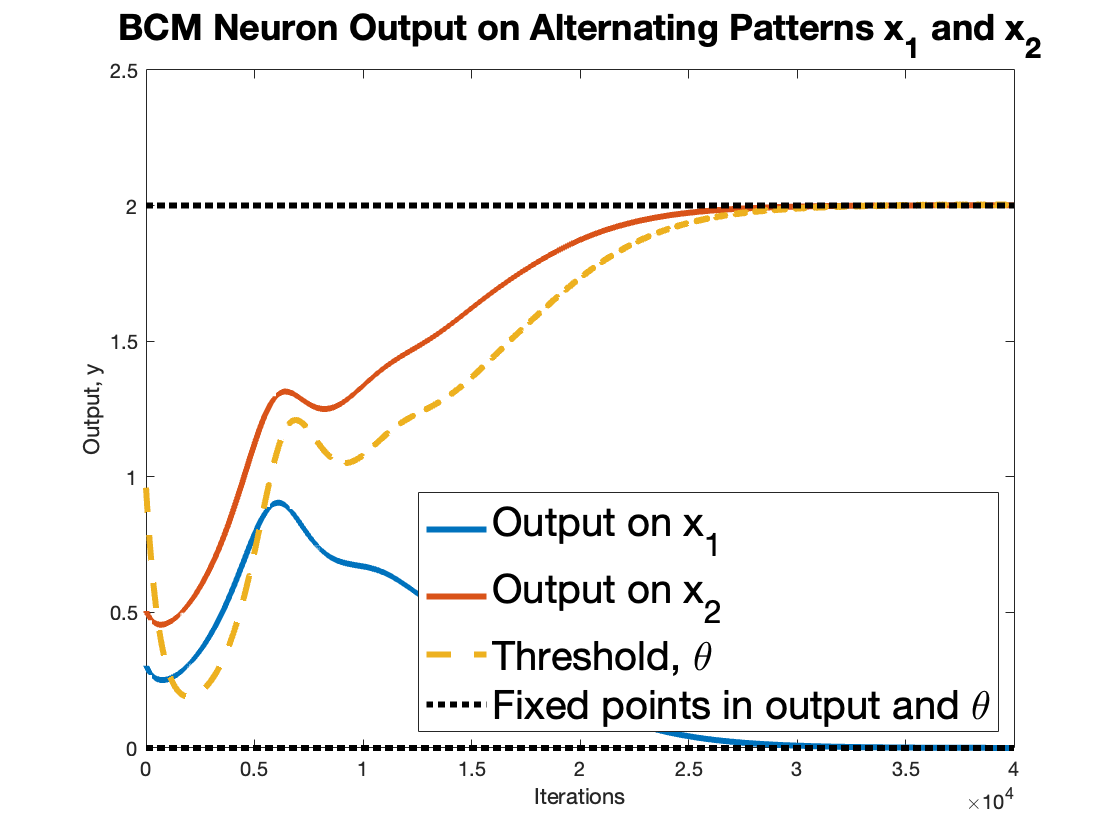

theta = rand;

% RUN SIMULATION
for i = 1:n_iters
    if mod(i,2) % This if statement ensures we alternate between inputs every iteration
        y_hist(i) = (inputx1) * w_BCM'; % get output
        w_BCM = BCM_mine(w_BCM, inputx1, y_hist(i), theta, eta); % get new weights
        w_hist(:, i) = w_BCM; 
    else
        y_hist(i) = (inputx2) * w_BCM';
        w_BCM = BCM_mine(w_BCM, inputx2, y_hist(i), theta, eta);
        w_hist(:, i) = w_BCM;
    end
    theta_hist(:, i) = theta;
    theta = theta_update_mine(theta, eta_theta, y_hist(i));
end

% CREATE PLOTS
figure;
plot(1:2:n_iters, y_hist(1:2:end), 'LineWidth',3); % Plot output on one input
hold on;
plot(2:2:n_iters, y_hist(2:2:end), 'LineWidth',3); % plot output on the other
plot(1:n_iters, theta_hist, 'LineWidth',3, 'LineStyle',"--"); % plot the threshold
% Show the fixed points:
plot(1:n_iters, 2 * ones([n_iters,1]), 'LineWidth', 3, 'LineStyle', ':','Color', "Black")
plot(1:n_iters, 0 * ones([n_iters,1]), 'LineWidth', 3, 'LineStyle', ':','Color', "Black")
title("BCM Neuron Output on Alternating Patterns x_1 and x_2", 'FontSize', 18)
legend("Output on x_1", "Output on x_2", "Threshold, \theta", "Fixed points in output and \theta",'Location',"southeast", 'FontSize', 20);
ylabel('Output, y')
xlabel('Iterations')

% Plot the weights (this plot does not include much since it was not used
% in the thesis)
figure;
for p = 1:2
    plot(1:n_iters, w_hist(p,:), 'LineWidth', 3);
    hold on;
end

legend("w_1", "w_2");

## A Test of Differentiation in the BCM Neuron

A test similar to the one done for the Simple Hebbian and Oja Rules for differentiation between patterned and random inputs. (95% random and 5% patterned input). This time the same inputs are used, but they are rescaled such that they are normal with a magnitude of one.

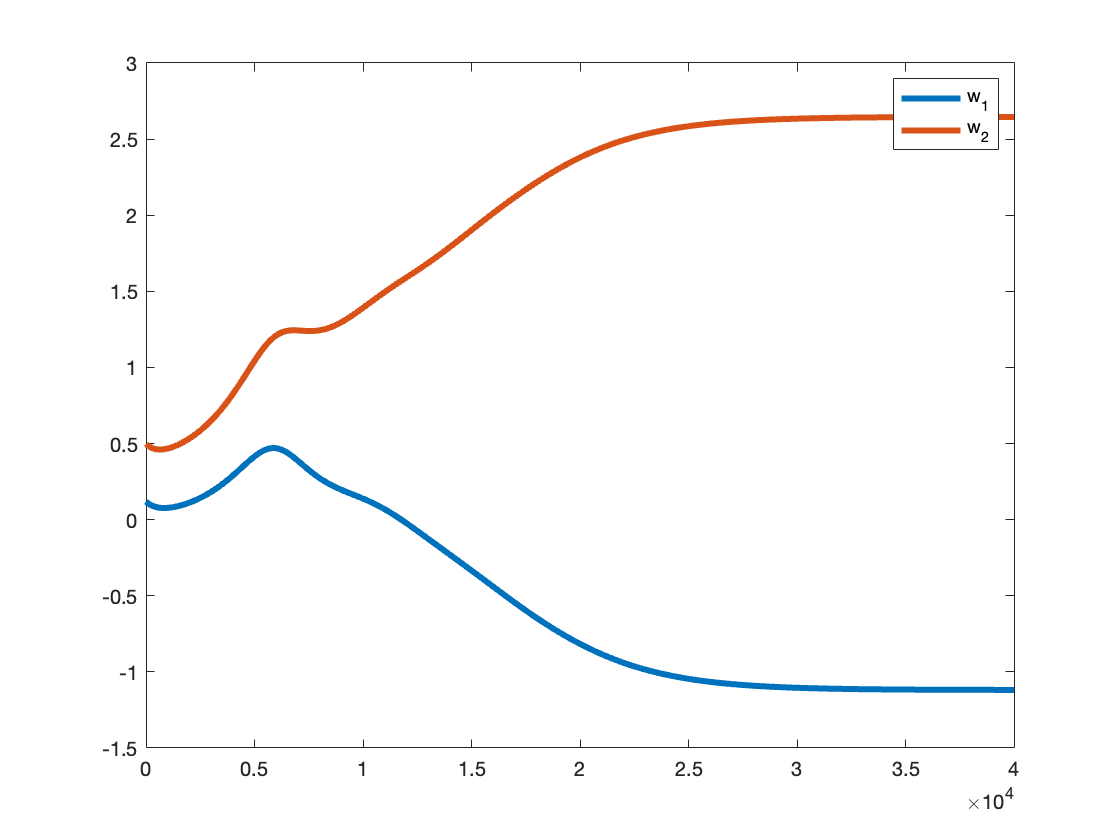

% Define parameters:
phi = 0.4;
n_iters = 80000;
eta = 0.001;
eta_theta = 1.7 * eta;
inputx2 = [0.9434; 0.0189; 0.0189; 0.0189]; % This is the normalized version of the patterned input fed to Hebb's and Oja's rules


% Set up variables to record weights outputs and thresholds
y_hist = zeros([1 n_iters]);
w_hist = NaN([4, n_iters]);
theta_hist = NaN([1, n_iters]);

% rnadomly init. weights and threshold
w_BCM = [rand rand rand rand];
theta = rand;

% For recording when the neuron encounters random or patterned input:
x1_indices = [];
x2_indices = [];

%SIMULATE
for i = 1:n_iters
    if rand < 0.95 % Then give random input
        x1_indices(end+1) = i;
        inputx1 = rand([1 4]);
        
        % Normalize the input:
        x1sum = sum(inputx1);
        for k = 1:length(inputx1)
            inputx1(k) = inputx1(k) / x1sum;
        end
        
        y_hist(i) = (inputx1) * w_BCM';
        w_BCM = BCM_mine(w_BCM, inputx1, y_hist(i), theta, eta);
        w_hist(:, i) = w_BCM;
        
    else % give patterned input
        x2_indices(end+1) = i;
        y_hist(i) = (inputx2)' * w_BCM';
        w_BCM = BCM_mine(w_BCM, inputx2', y_hist(i), theta, eta);
        w_hist(:, i) = w_BCM;
    end
    theta_hist(:, i) = theta;
    theta = theta_update_mine(theta, eta_theta, y_hist(i));

end
% Plot the outputs and threshold
figure;
plot(x1_indices, y_hist(x1_indices), 'LineWidth',1);
hold on;
plot(x2_indices, y_hist(x2_indices), 'LineWidth',3);
plot(1:n_iters, theta_hist, 'LineWidth', 3, 'LineStyle',"--")

% Commented-out lines are for plotting fixed points on 95% pattern
%plot(1:n_iters, 1 / 0.95 * ones([n_iters, 1]), "LineStyle", ":", "LineWidth", 3, "Color", "Black")
%plot(1:n_iters, 0 * ones([n_iters, 1]), "LineStyle", ":", "LineWidth", 3, "Color", "Black")
legend("Output on noise", "Output on pattern", 'Threshold, \theta', 'Fixed Points in output and \theta','FontSize', 20, 'Location', 'Southeast');
ylabel('Output, y', 'FontSize',20)
xlabel('Iterations', 'FontSize',20)
title('Output of the BCM-Trained Neuron', 'FontSize',20)
subtitle('On 95% patterned input', 'FontSize',20)

% Plot weights
figure;
for p = 1:4
    plot(1:n_iters, w_hist(p,:), 'LineWidth', 3);
    hold on;
end
legend("w_1", "w_2");

## A Test of "Recollection" between **two patterns **in the BCM Neuron

A test done for "recollection" with the inputs devised by Udeigwe *et al. *(This simulation is not used in the thesis). The neuron is exposed to a pattern for a certain amount of iterations then solely exposed to another one before being re-triggered with the first to test its recall ability.

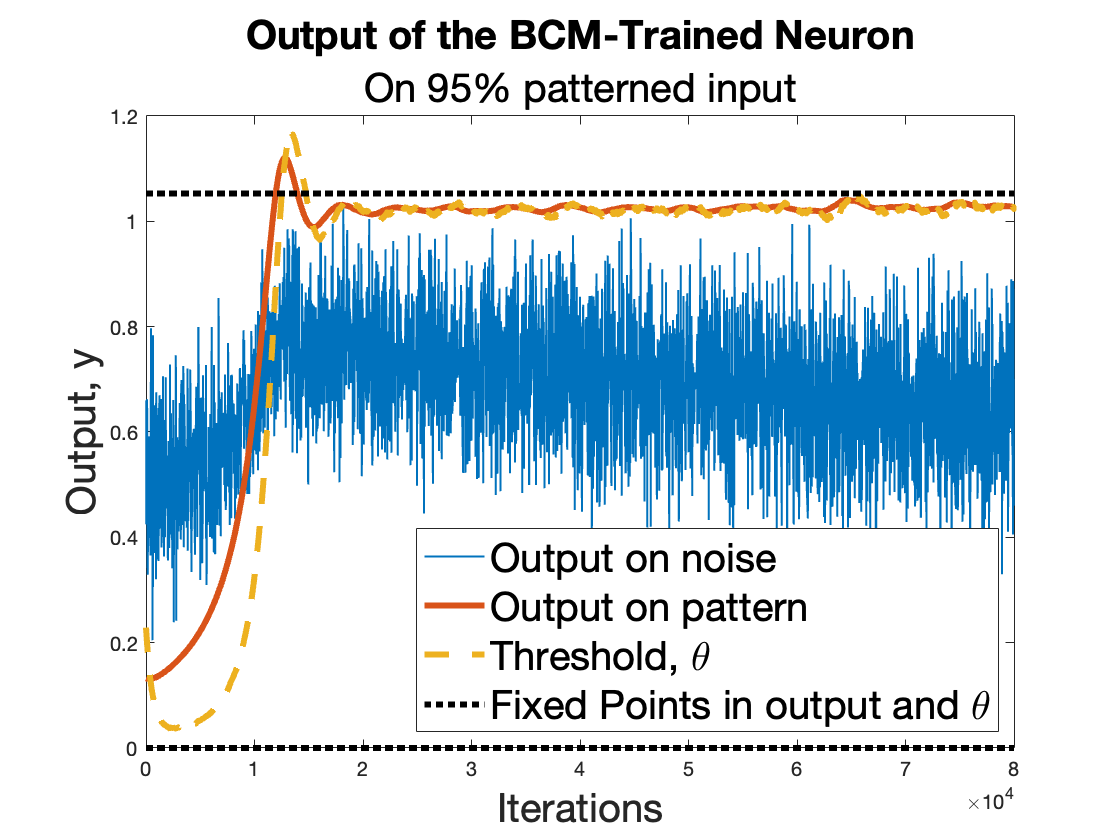

% Define parameters:
phi = 0.4;

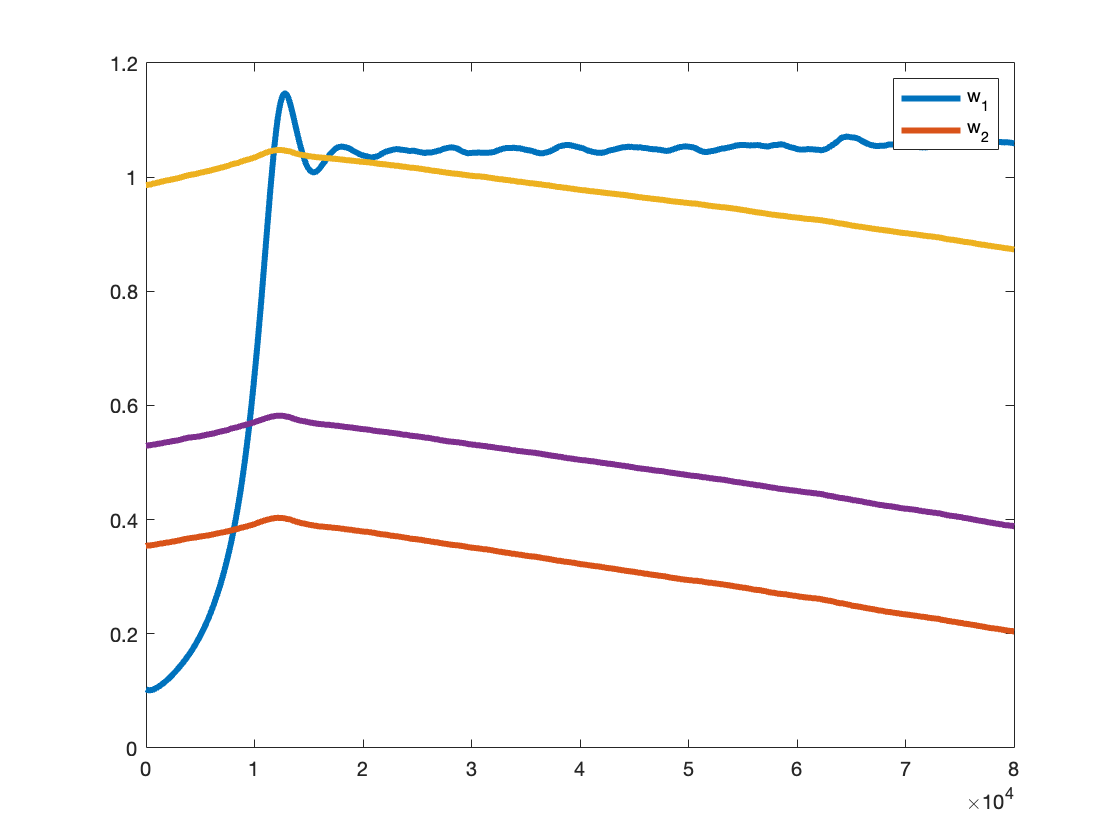

n_iters = 2000;
eta = 0.25;
eta_theta = 1.7 * eta;
inputx1 = [cos(phi) sin(phi)]
inputx2 = [sin(phi) cos(phi)]

% Check for stability according to our conditions
[z1, z2] = stability_checker(inputx1, inputx2, 0.5, eta, eta_theta) 


% initialize storing variables
w_hist = NaN([2, n_iters]);
y_hist = zeros([1 n_iters]);

% init weights and threshold
w_BCM = [rand rand];
theta = rand;


inputx1 =     0.9211    0.3894


%SIMULATE

inputx2 =     0.3894    0.9211


for i = 1:n_iters
    % For the first fifth of the sim, expose to pattern 1
    if i < n_iters / 5 

z1 = logical
   1


z2 = logical
   1


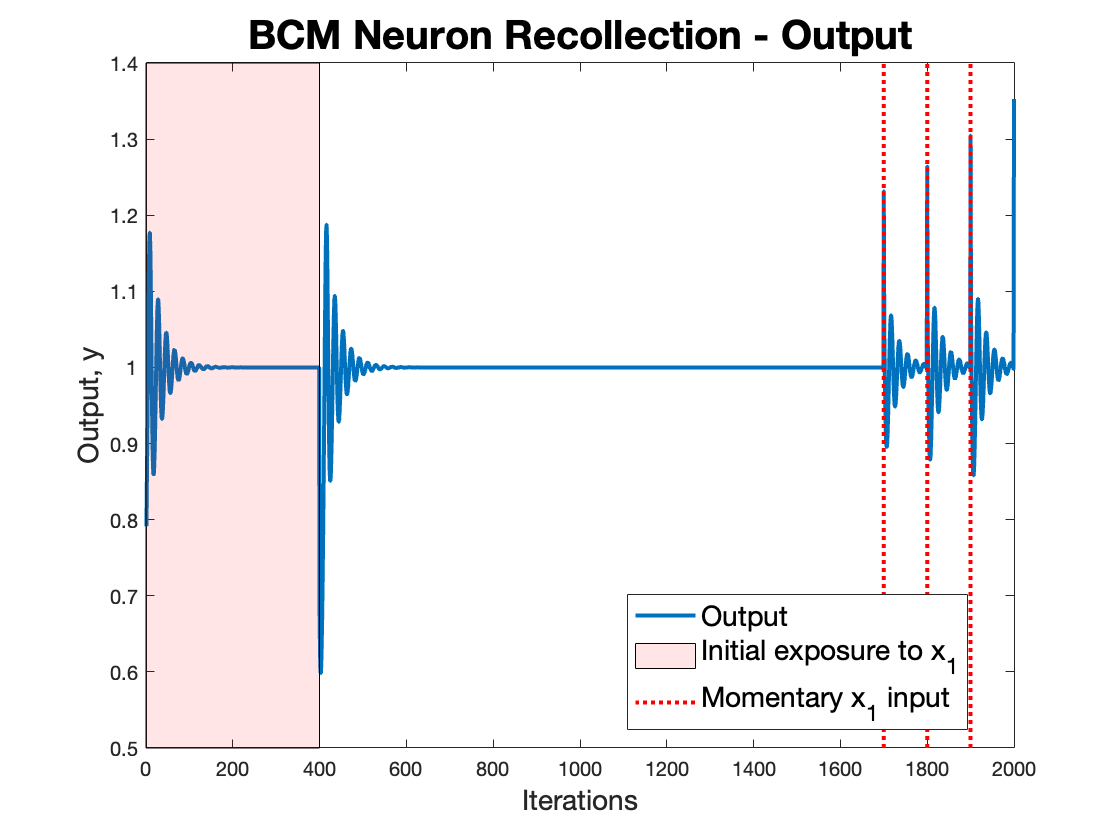

        y_hist(i) = (inputx1) * w_BCM';
        w_BCM = BCM_mine(w_BCM, inputx1, y_hist(i), theta, eta);
        w_hist(:, i) = w_BCM;
    % At some sparse iterations towards the end of the simulation re
    % submit the original pattern 1
    elseif i > 4 * n_iters /5 && mod(i, 100) == 0
        y_hist(i) = (inputx1) * w_BCM';
        w_BCM = BCM_mine(w_BCM, inputx1, y_hist(i), theta, eta);
        w_hist(:, i) = w_BCM;
    % Otherwise, in between, input pattern 2
    else
        y_hist(i) = (inputx2) * w_BCM';
        w_BCM = BCM_mine(w_BCM, inputx2, y_hist(i), theta, eta);
        w_hist(:, i) = w_BCM;
    end
    % Update theta
    theta = theta_update_mine(theta, eta_theta, y_hist(i));
end
% First plot output
figure;
plot(1:n_iters, y_hist, 'LineWidth',2);
hold on;
% Code for drawing the highlighted red box for the duration of the initial
% exposure to the preferred pattern
yl = ylim;
patch([0 0 400 400], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
% Dotted lines denoting the trigger again of the original patterns:
plot([1700 1700], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([1800 1800], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([1900 1900], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
legend("Output", "Initial exposure to x_1", "Momentary x_1 input", 'Location',"best", 'FontSize', 14);
title("BCM Neuron Recollection - Output", "FontSize", 20)
xlabel("Iterations", "FontSize", 14);
ylabel("Output, y", "FontSize", 14)

% plot weights
figure;
for p = 1:2
    plot(1:n_iters, w_hist(p,:), 'LineWidth', 2);
    hold on;
end
yl = ylim;
patch([0 0 400 400], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
plot([1700 1700], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([1800 1800], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
plot([1900 1900], [yl(1) yl(2)], 'LineStyle',":", "LineWidth",2, "Color","red");
legend("w_1", "w_2", "Initial exposure to x_1", "Momentary x_1 input", 'Location',"best", 'FontSize', 14);

title("BCM Neuron Recollection - Weights", "FontSize", 20)
xlabel("Iterations", "FontSize", 14);
ylabel("Synaptic Weight", "FontSize", 14)

## Recollection with random noise

The same test done for recall ability that is performed for Oja's Rule. This time the neuron is exposed to a pattern for an initial period, then exposed to only random noise for the rest of the duration. Outputs to both the noise and the pattern are monitored even when the neuron is not receiving the patterned input. Again, both the noise and the pattern are normalized, in contrast to the input used in Oja's Rule and the Simple Hebbian Rule.

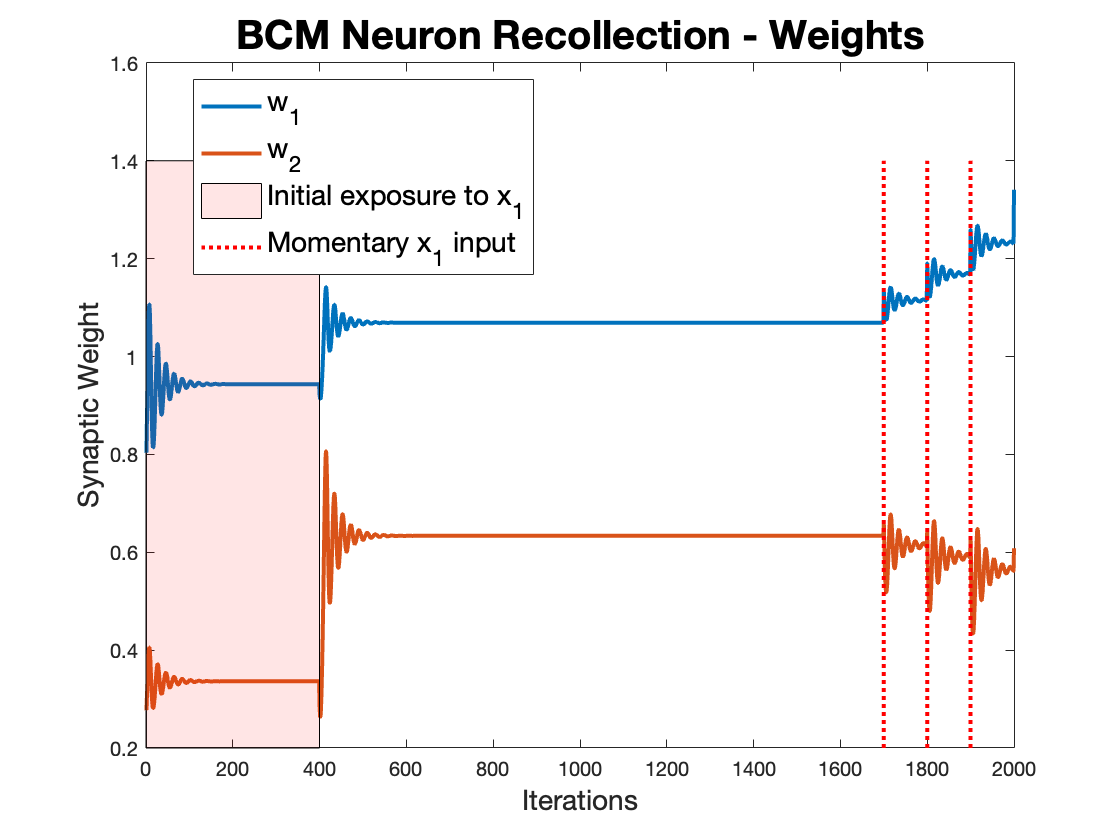

% Initialize parameters
n_iters = 100000;
eta = 0.01;
eta_theta = 1.7 * eta;
inputx2 = [0.9434; 0.0189; 0.0189; 0.0189];
w_BCM = [rand rand rand rand];
theta = rand;

% variables for storing history of outputs, weights and threshold:
y_hist1 = zeros([1 n_iters]); % output on random input
y_hist2 = zeros([1 n_iters]); % output on patterned input
w_hist = NaN([4, n_iters]);
theta_hist = NaN([1, n_iters]);


%SIMULATE
for i = 1:n_iters
    if i >= n_iters / 5 % For first fifth of simulation, expose neuron to the pattern
        
        inputx1 = rand([1 4]);
        % normalize random noise
        x1sum = sum(inputx1);
        for k = 1:length(inputx1)
            inputx1(k) = inputx1(k) / x1sum;
        end
        
        y_hist1(i) = (inputx1) * w_BCM'; % calculate output on noise
        y_hist2(i) = inputx2' * w_BCM'; % calculate output on pattern

        % update weights and theta according to the output on the pattern
        w_BCM = BCM_mine(w_BCM, inputx1, y_hist1(i), theta, eta);
        w_hist(:, i) = w_BCM;
        theta = theta_update_mine(theta, eta_theta, y_hist1(i));
        
    else % Expose the neuron to normalized random noise
        
        inputx1 = rand([1 4]);
        % normalize the random input:
        x1sum = sum(inputx1);
        for k = 1:length(inputx1)
            inputx1(k) = inputx1(k) / x1sum;
        end
        y_hist1(i) = inputx1 * w_BCM'; % calculate output on noise
        y_hist2(i) = (inputx2') * w_BCM'; % calculate output on pattern

        % Update weights with respect to the output on noise input
        w_BCM = BCM_mine(w_BCM, inputx2', y_hist2(i), theta, eta);
        w_hist(:, i) = w_BCM;
        theta = theta_update_mine(theta, eta_theta, y_hist2(i));
    end
    theta_hist(:, i) = theta;
end

% Plot output, threshold over time
figure;
plot(1:n_iters, y_hist1, 'LineWidth',2);
hold on;
plot(1:n_iters, y_hist2, 'LineWidth',2);
plot(1:n_iters, theta_hist, 'LineWidth', 2);
% Code for creating highlighted red patch denoting pattern exposure
yl = ylim;
patch([0 0 n_iters / 5 n_iters / 5], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
legend("Output on random input", "Output on patterned input", "Threshold", 'Initial exposure to patterned input', 'Location',"southeast", 'FontSize', 14);
title("BCM Neuron Recollection - Output", "FontSize", 20)
xlabel("Iterations", "FontSize", 14);
ylabel("Output, y", "FontSize", 14)

% Plot for weights
figure;
for p = 1:2
    plot(1:n_iters, w_hist(p,:), 'LineWidth', 2);
    hold on;
end
yl = ylim;
patch([0 0 400 400], [yl(1) yl(2) yl(2) yl(1)], 'white', 'FaceColor', 'red', 'FaceAlpha', 0.1);
legend("w_1", "w_2", "Initial exposure to x_1", 'Location',"best", 'FontSize', 14);
title("BCM Neuron Recollection - Weights", "FontSize", 20)
xlabel("Iterations", "FontSize", 14);
ylabel("Synaptic Weight", "FontSize", 14)


% Function for updating theta as discrete time-difference

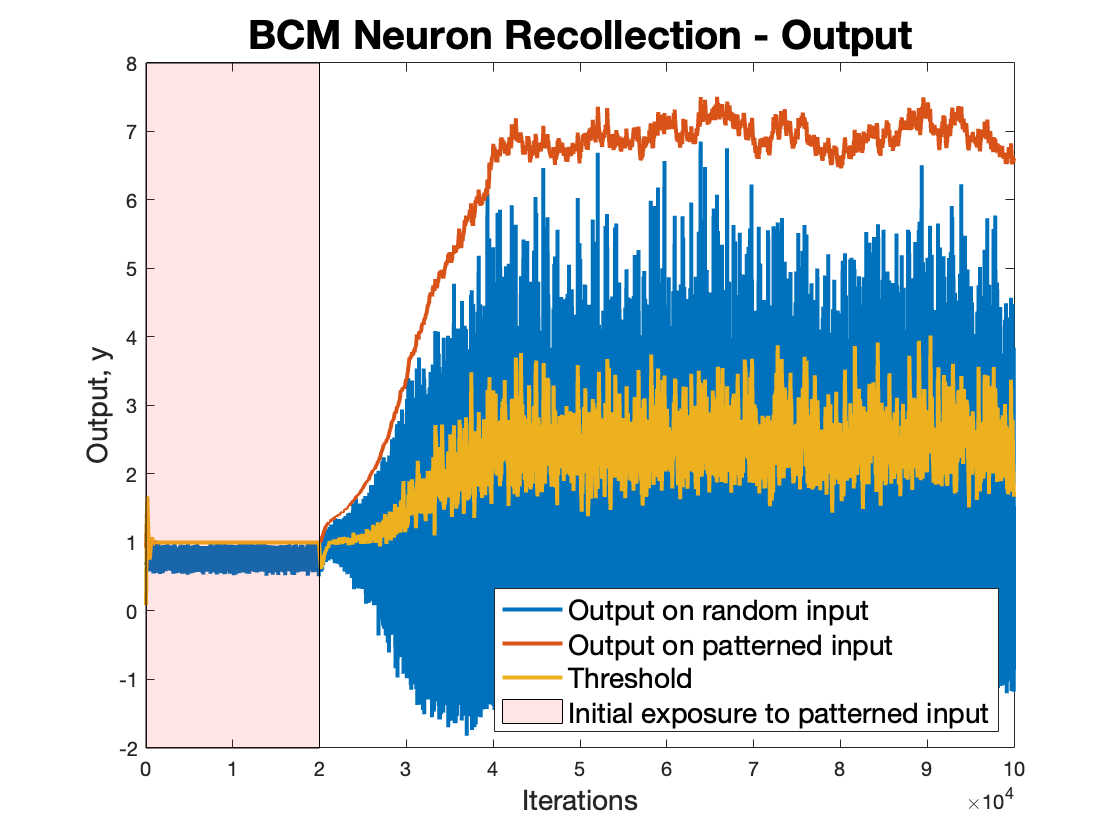

function [new_theta] = theta_update_mine(theta, eta_theta, y)

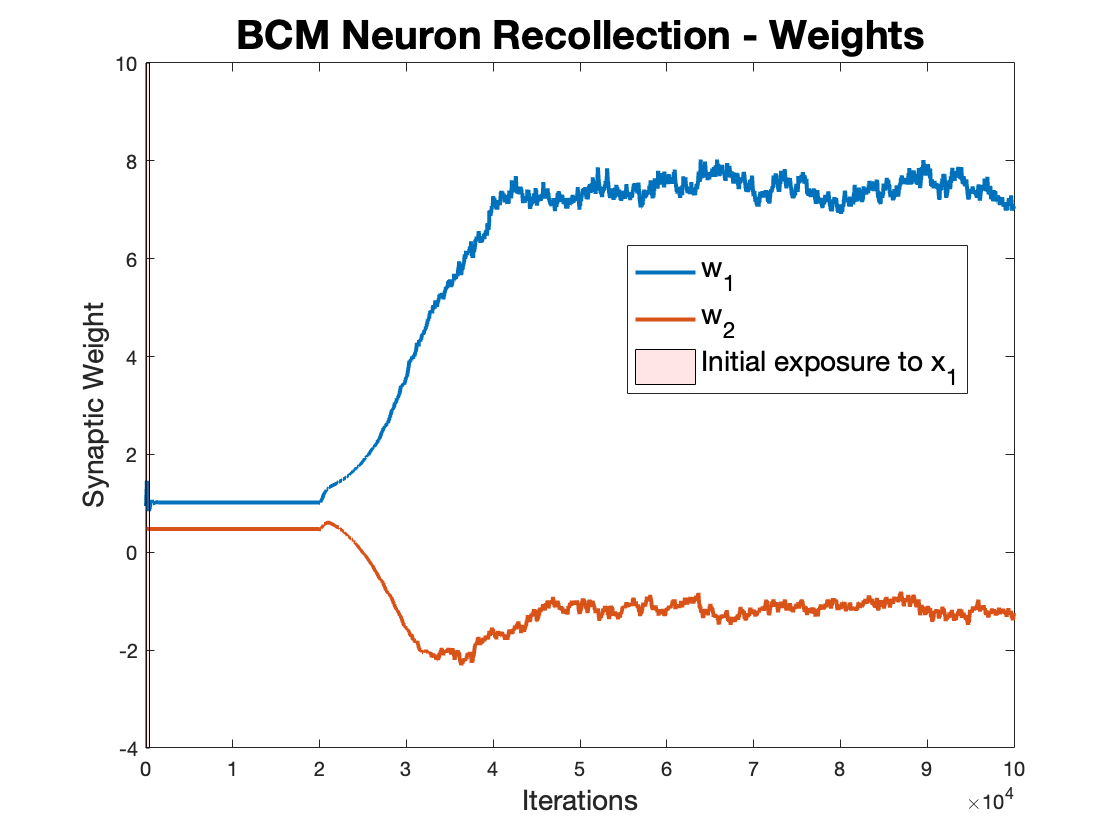

    new_theta = theta + eta_theta * (y^2 - theta);
end
% Function for updating weights as discrete time-difference
function [new_weight] = BCM_mine(w,x, y, theta, eta_w)
    new_weight = w + (eta_w * y * x * (y-theta));% - eta_null .* w;
end
% Function for checking the stability of the input parameters
% returns stability of FP (1/rho, 0 , 1/rho) then (0, 1/(1-rho), 1/(1-rho))
function [z1stable, z2stable] = stability_checker(x_1, x_2, rho, eta_w, eta_theta)
    tau = eta_w / eta_theta;
    a = x_2 * x_2';
    b = x_1 * x_2';
    c = rho / (1-rho);

    z1stable = c*(a-b^2) * (1 * (a*c)) * tau^2 - (1 +2*a*c - a^2 * c^2 - 2 * b^2*c) * tau + (1 + a*c) > 0;
    z2stable = c * (a-b^2) * (a-c) * tau^2 + (2*c*(b^2-a) + c^2 - a^2) * tau + a + c > 0;
end